# PW2 - Interpolation Methods

## I- Polynomial interpolation

The following function is given,

**(a) Plot this function f under MATLAB, by creating a matlab function f.m.**

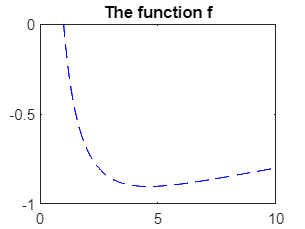

xr = 1:0.01:10;
plot(xr,f(xr),'b--')
title('The function f')

**b) Calculate the values of the function at points x0 = 1, x1 = 2, x2 = 4, x3 = 8, x4 = 10.**

x = [1,2,4,8,10];
y = f(x)

y =          0   -0.6990   -0.8979   -0.8469   -0.8000


**c) Calculate the Lagrange polynomial of degree 4 interpolating this function.**

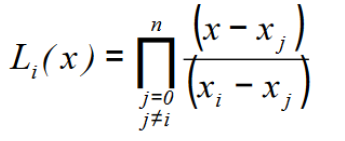

$$equ(s) = \frac{821765912354371001\,s^{4}}{311288806243848683520}-\frac{1358727987274494203\,s^{3}}{20752587082923245568}+\frac{4402723882335228179\,s^{2}}{7782220156096217088}-\frac{10259474235862301005\,s}{5188146770730811392}+\frac{28688665797193248449}{19455550390240542720}$$

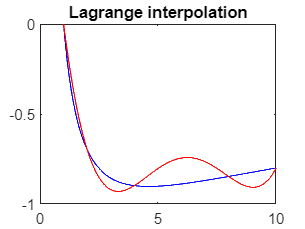

$$equa\_1(s) = \frac{821765912354371001\,s^{4}}{311288806243848683520}-\frac{1358727987274494203\,s^{3}}{20752587082923245568}+\frac{4402723882335228179\,s^{2}}{7782220156096217088}-\frac{10259474235862301005\,s}{5188146770730811392}+\frac{28688665797193248449}{19455550390240542720}$$

 x=[1,2,4,8,10];
 n = length(x);
equa_1 = Lagrange(x,n)

**d) Give the number of divisions made to calculate the coefficients.**

If the algorithm has been analyzed, it can be noticed that there are two for loops. But in the first loop iterates until n and second loop iterates until n-1 (because i~=j).

So, the total multiplication is n*(n-1). So, in another word,  number of divisions made to calculate the coefficients $\frac{1}{n\left(n-1\right)}=\frac{1}{5\left(5-1\right)}=\frac{1}{20}$.

**e) What is the approximate value of the function at points x = 2.9 and x = 5.25? Give the value of the error.**

x1 = double(equa_1(2.9)) % for 2.9

x1 = -0.9123

x2 = double(equa_1(5.25)) % for 5.25 

x2 = -0.7826

y1 = f(2.9)

y1 = -0.8479

y2 = f(5.25)

y2 = -0.8989

error1 = y1 - x1

error1 = 0.0644

error2 = y2 - x2

error2 = -0.1163

## I- B Newton interpolation

**a) Plot this function under MATLAB in the interval [-5, 5], creating a function g.m.**

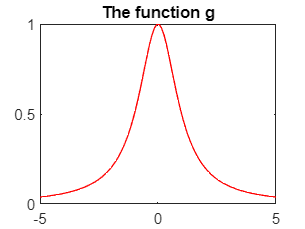

x = linspace(-5,5);
plot(x,g(x),'r-')
title('The function g')

**b) Calculate the values of the function at points x0 = -5, x1 = -3, x2 = -1, x3 = 1, x4 = 3, x5 = 5.**

x_n = [-5:2:5];
n = length(x_n)

n = 6

y_n = g(x_n)

y_n =     0.0385    0.1000    0.5000    0.5000    0.1000    0.0385


% x_n_1 = [-7:2:7];

**c) Calculate the Newtonian polynomial P of degree n = 5 interpolating this function g. We will program the algorithm of divided differences.**

P = newton(x_n,n)

$$equ(s) = \frac{s^{4}}{520}-\frac{9\,s^{2}}{130}+\frac{59}{104}$$

$$P(s) = \frac{s^{4}}{520}-\frac{9\,s^{2}}{130}+\frac{59}{104}$$

**d) Write a program making it possible to calculate the value of the polynomial at any point.**

P(-5)

$$ans = \frac{1}{26}$$

**e) Plot on the same graph the function g as well as the polynomial P. Examine the edge effects.**

x_n = [-5:2:5];
n = length(x_n);
P = newton(x_n,n);

$$equ(s) = \frac{s^{4}}{520}-\frac{9\,s^{2}}{130}+\frac{59}{104}$$

x_m = [-5:1:5];
m = length(x_m);
P1 = newton(x_m,m);

$$equ(s) = -\frac{s^{10}}{44200}+\frac{7\,s^{8}}{5525}-\frac{83\,s^{6}}{3400}+\frac{2181\,s^{4}}{11050}-\frac{149\,s^{2}}{221}+1$$

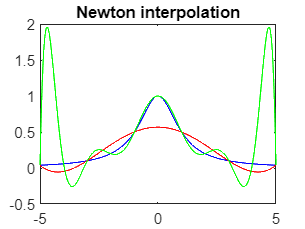

xt=-5:0.01:5;
plot(xt,g(xt),'b',xt,P(xt),'r-',xt,P1(xt),'g-')
title('Newton interpolation')

There are some oscillation around the interval's edges, as can be seen. This is solely attributable to high-degree polynomials over a set of evenly spaced interpolation points. Runge's phenomenon is the name given to this phenomenon.

**f) How do these effects evolve with the order of the polynomial?**

As mentioned earlier, there are some oscillation in another word edge effect can be noticed. The number of oscillation will increase according to the polynomial order. 

So, it can be said that the more the polynomial order is the more the oscillations can be noticed which is due to more critical points. As a result, the effects evolve more.

**g) Go back to the 5 previous questions by taking, as a subdivision of the interval, Chebychev's points on the interval [a, b] = [-5, 5],**

n=6;
b=5;
a=-5;
eq = chebychev(a,b,n)

$$equ(s) = \frac{40\,s^{5}}{29783}+\left(\frac{100\,\sqrt{3}}{29783}+\frac{88215600526848191426388123762899}{75508875653194712529552623131426816}\right)\,s^{4}+\left(\frac{441078002634240957131940618814495\,\sqrt{3}}{151017751306389425059105246262853632}-\frac{1034892834927928099153133126758282837561419250809599}{26786402009000788684837135614024035184253931647664128}\right)\,s^{3}+\left(-\frac{5174464174639640495765665633791414187807096254047995\,\sqrt{3}}{53572804018001577369674271228048070368507863295328256}-\frac{9949160593497737648600295673776221917106547780022333}{696446452234020505805765525964624914790602222839267328}\right)\,s^{2}+\left(\frac{152693751901318340923636685101534318907752478284520005}{696446452234020505805765525964624914790602222839267328}-\frac{49745802967488688243001478368881109585532738900111665\,\sqrt{3}}{1392892904468041011611531051929249829581204445678534656}\right)\,s+\frac{700197738462568942898971268260609704774708780395758425\,\sqrt{3}}{1392892904468041011611531051929249829581204445678534656}+\frac{242261772532054011}{1873497444986126336}$$

$$eq(s) = \frac{40\,s^{5}}{29783}+\left(\frac{100\,\sqrt{3}}{29783}+\frac{88215600526848191426388123762899}{75508875653194712529552623131426816}\right)\,s^{4}+\left(\frac{441078002634240957131940618814495\,\sqrt{3}}{151017751306389425059105246262853632}-\frac{1034892834927928099153133126758282837561419250809599}{26786402009000788684837135614024035184253931647664128}\right)\,s^{3}+\left(-\frac{5174464174639640495765665633791414187807096254047995\,\sqrt{3}}{53572804018001577369674271228048070368507863295328256}-\frac{9949160593497737648600295673776221917106547780022333}{696446452234020505805765525964624914790602222839267328}\right)\,s^{2}+\left(\frac{152693751901318340923636685101534318907752478284520005}{696446452234020505805765525964624914790602222839267328}-\frac{49745802967488688243001478368881109585532738900111665\,\sqrt{3}}{1392892904468041011611531051929249829581204445678534656}\right)\,s+\frac{700197738462568942898971268260609704774708780395758425\,\sqrt{3}}{1392892904468041011611531051929249829581204445678534656}+\frac{242261772532054011}{1873497444986126336}$$

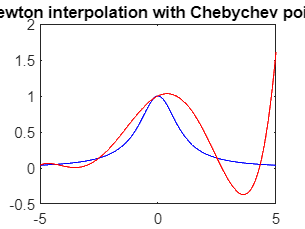

title('Newton interpolation with Chebychev points')

**h) Conclude.**

It may be established that interpolation of higher order newton polynomials leads in unanticipated oscillations (edge effect). Surprisingly, using interpolation with a large number of points can result in more error due to oscillations. As a result, the Chebyshev points are used to reduce the error caused by Runge's phenomenon. 

## II- Spline interpolation

## I- A Quadratic spline 

**a) Write a general program of interpolation by quadratic splines. The program receives, as input, the pairs (xi, yi), i = 0, 1,…, n as well as the value of the derivative at point x0. The program will return a 3 x n matrix containing the coefficients of the polynomials Si(x).**

n=6;

x=[-5,-3,-1,1,3,5];
y=zeros(1,n);

for i=1:n
    y(i)=g(x(i));
end

[a,b,c]=qs(x,y,0)

a =     0.0154    0.0692   -0.1692    0.0692    0.0154


b =          0    0.0615    0.3385   -0.3385   -0.0615


c =     0.0385    0.1000    0.5000    0.5000    0.1000


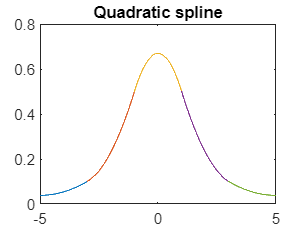

for i=1:n-1
    xt=x(i):0.01:x(i+1);
    plot(xt,a(i)*(xt-x(i)).^2+b(i)*(xt-x(i))+c(i) );
    hold on;
end
hold off
title('Quadratic spline')

**b) Apply to points X = [0, 1, 2, 3]; Y = [0, 0.5, 2.0, 1.5] as well as to the function of Runge.**

n=4;

x=[0, 1, 2, 3];
y = [0, 0.5, 2.0, 1.5];
[a,b,c]=qs(x,y,0)

a =     0.5000    0.5000   -2.5000


b =      0     1     2


c =          0    0.5000    2.0000


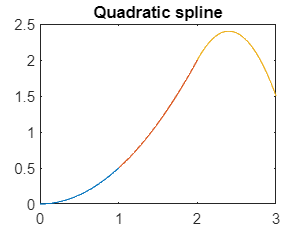


for i=1:n-1
    xt=x(i):0.01:x(i+1);
    plot(xt,a(i)*(xt-x(i)).^2+b(i)*(xt-x(i))+c(i) )
    hold on
end
hold off
title('Quadratic spline')

**c) Examine the effect of different values of S’(x0).**

 A spline of degree 2 is a piecewise quadratic function on each subinterval. The first derivative exists and is continuous, but it is not smooth.

We can see by comparing the multiple values of S'(x0) that when we increase and decrease the value of S'(x0) away from zero, the final quadratic spline will have more oscillations. In this respect, selecting smaller numbers closer to zero assists us in obtaining a more piecewise linear interpolation of the curve.

It can also noticed that the number of the equation is more than unknown value and the tangent is also changing. Moreover each part of the interpolation has almost one zero.

## I- B Cubic spline

**a) Write a main program of interpolation by cubic splines. The program receives, as input, the pairs (xi, yi), i = 0, 1,…, n as well as the value of the derivative at point x0. The program will return a 4 x n matrix containing the coefficients of the polynomials Si(x).**


n=7;

x=[-5,-3,-1,0,1,3,5];
y=zeros(1,n);

for i=1:n
    y(i)=g(x(i));
end


[a,b,c,d]=cs(x,y,0,0)

a =    -0.0021    0.0529   -0.4023    0.4023   -0.0529    0.0021


b =          0   -0.0127    0.3046   -0.9023    0.3046   -0.0127


c =     0.0392    0.0138    0.5977         0   -0.5977   -0.0138


d =     0.0385    0.1000    0.5000    1.0000    0.5000    0.1000


**b) Apply to points X = [0, 1, 2, 3]; Y = [0, 0.5, 2.0, 1.5] as well as to the function of Runge. **

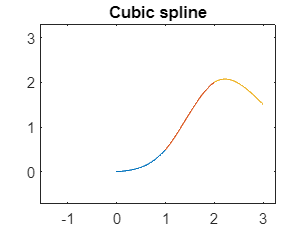

n=4;

x=[0, 1, 2, 3];
y = [0, 0.5, 2.0, 1.5];

[a,b,c,d]=cs(x,y,0,0);

for i=1:n-1
    xt=x(i):0.01:x(i+1);
    plot(xt,a(i)*(xt-x(i)).^3 + b(i)*(xt-x(i)).^2 + c(i)*(xt-x(i))+ d(i) )
    hold on;
end
hold off
title('Cubic spline')

sdsd


n=7; 

x=[-5,-3,-1,0,1,3,5];
y=zeros(1,n);

for i=1:n
    y(i)=g(x(i));
end


[a,b,c,d]=cs(x,y,0,0)

a =    -0.0021    0.0529   -0.4023    0.4023   -0.0529    0.0021


b =          0   -0.0127    0.3046   -0.9023    0.3046   -0.0127


c =     0.0392    0.0138    0.5977         0   -0.5977   -0.0138


d =     0.0385    0.1000    0.5000    1.0000    0.5000    0.1000


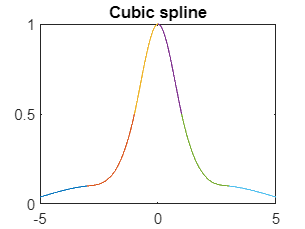


for i=1:n-1
    xt=x(i):0.01:x(i+1);
    plot(xt,a(i)*(xt-x(i)).^3 + b(i)*(xt-x(i)).^2 + c(i)*(xt-x(i))+ d(i) )
    hold on;
end
hold off
title('Cubic spline')

**The results obtained by polynomial interpolation, quadratic and cubic splines will be plotted on the same graph. Compare and conclude.**

% Lagrange Interpolation
%  x = 1:0.5:10;
%  n = length(x);   
%  syms s;
% equ(s)=0*s;
% l=ones(1,n);
% 
% for i=1:n
%     tmp=1+0*s;
%     for j=1:n
%         if i~=j
%             l(i)=l(i)/(x(i)-x(j));
%             tmp=tmp*(s-x(j));
%         end
%     end
%     
%     equ(s)=equ(s)+y(i)*l(i)*tmp;
% end
% 
% equ(s)=collect(equ(s))
% 
% plot(x,equ(x),'r-');

% Newton Interpolation


% quadratic splines Interpolation

% cubic splines Interpolation
